# Tutorial 2 - Mätvärdesbehandling

**Börja med att högerklicka i det vita området till höger och välj "Clear All Output".**

Denna tutorial exemplifierar

- medelvärde

- standardavvikelse

- standardosäkerhet hos medelvärde

## Kast med två stycken 6-sidiga tärningar

Vi kastar två stycken 6-sidiga tärningar och adderar ögonen på tärningarna. Vi kan då få ett resultat mellan 2-12, där 7 är det mest sannolika utfallet. Vi vill beräkna medelvärdet, standardavvikelsen och standardosäkerheten hos medelvärdet för våra tärningskast.

Vi börjar med att simulera 1000 tärningskast.

close all
clear all
% dice_1 och dice_2 simulerar våra rullade tärningar. Vi slumpar en siffra
% mellan 1-6 med randi-funktionen ("random integer") 1000 gånger.
dice_1 = randi(6, 1000, 1);
dice_2 = randi(6, 1000, 1);

% Vi summerar resultaten från de enskilda tärningarna
dice_sum = dice_1 + dice_2

dice_sum =      9
     9
     7
     8
     8
     5
     5
     5
     7
     9



% och ritar upp resultatet i ett histogram
hist = histogram(dice_sum);
xlabel("Tärningsutslag")
ylabel("Antal utfall")

### Medelvärde

Vi börjar med att hitta medelvärdet av tärningsutslagen med mean() funktionen.

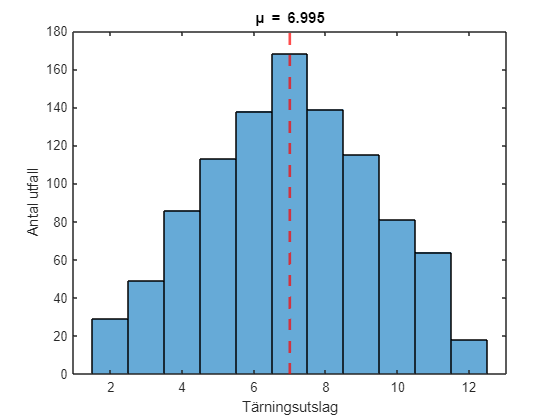

% Vi beräknar medelvärdet med mean() funktionen
dice_mean = mean(dice_sum);

% Vi ritar en röd streckad linje i figuren motsvarande medelvärdet.
hold on
xline(dice_mean, "Color", "red", "LineStyle", "--", "LineWidth", 2);

% och skriver ut resultatet i figuren
txt_mean = "\mu = " + num2str(dice_mean);
title(txt_mean)

### Standardavvikelse

Standardavvikelsen är ett mått spridningen av mätvärdena runt medelvärdet

Färdigställ följande kodblock (ta bort %-tecknet från och fyll i de rader du vill att Matlab ska exekvera).

% Vi beräknar standardavvikelsen för dice_sum med std() funktionen
% ----- Fyll i raden under -----
% dice_std = 

% Vi ritar två gröna streckade linjer i figuren som motsvarar standardavvikelsen
% En till höger om medelvärdet (dice_mean + standardavvikelsen) 
% En till vänster om medelvärdet (dice_mean - standardavvikelsen).
% ----- Fyll i raderna under -----
% xline( , "Color", " ", "LineStyle", " ", "LineWidth", 2);
% xline( , "Color", " ", "LineStyle", " ", "LineWidth", 2);

% och skriver ut resultatet i figuren
% ----- Fyll i raden under -----
% txt_std = "\sigma = " + num2str();
% title(txt_std);

% Facit finns längst ner i dokumentet

I följande block simuleras två viktade fusktärningar som är designade att ge resultatet 7 oftare än vad ärliga tärningar skulle. Kör kodblocket nedan (funktionen weighted_dicte() kallar på en funktion längst ner i dokumentet som du kan ignorera) och **jämför standardavvikelsen** för denna med standardavvikelsen som erhölls i föregående kodblock med ärliga tärningar.

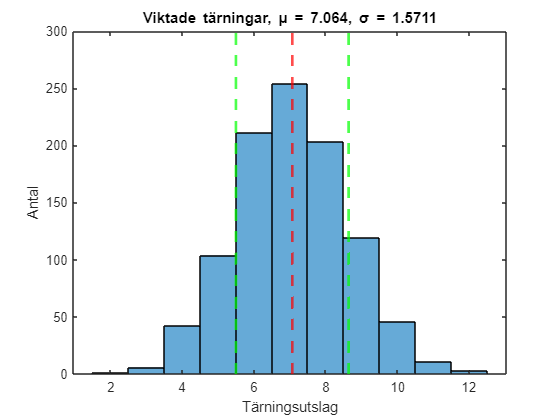

weighted_dice();

Är standardavvikelsen större eller mindre för den viktade tärningen? Varför?

### Standardosäkerheten hos ett medelvärde

*Standardosäkerheten hos ett medelvärde* ger en uppskattning på hur mycket *medelvärdet *skulle variera mellan experiment om vi upprepade experimentet flera gånger, och definieras

        
$$u\left(\bar{x}\right) = \frac{\text{std}(x)}{\sqrt{n}}$$


där $\text{std}(x)$är standardavvikelsen av mätvärdena $x$ och $n$ är antalet mätvärden. Vi använder samma tärningsexempel som tidigare för att exemplifiera.

#### Först utför vi experimentet en gång. Ett experiment ser vi här som 100 kast.

% Vi rullar två tärningar 100 gånger och summerar ögonen vid varje kast
dice_throws = 100;
dice_a = randi(6, dice_throws, 1);
dice_b = randi(6, dice_throws, 1);
sum_single = dice_a + dice_b;

% och beräknar medelvärdet
mean_single = mean(sum_single)

mean_single = 7.1200

#### Sen utför vi samma experiment, fast 500 gånger.

% Vi gör samma sak som i kodblocket ovanför 500 gånger (d.v.s. 500*100 tärningskast)
n_experiments = 500;
mean_multi = zeros(n_experiments, 1); % Vi vill spara medelvärdena i den här vektorn

% Vi loopar 500 gånger
for i = 1:n_experiments
    dice_A = randi(6, dice_throws, 1);
    dice_B = randi(6, dice_throws, 1);
    sum_multi = dice_A + dice_B;
    
    % och sparar medelvärdet för varje experiment i vår mean_multi vektor
    mean_multi(i) = mean(sum_multi);
end
mean_multi

mean_multi =     6.9800
    6.7300
    6.8700
    7.0200
    6.6700
    7.1500
    7.2800
    6.7300
    6.9700
    6.7400


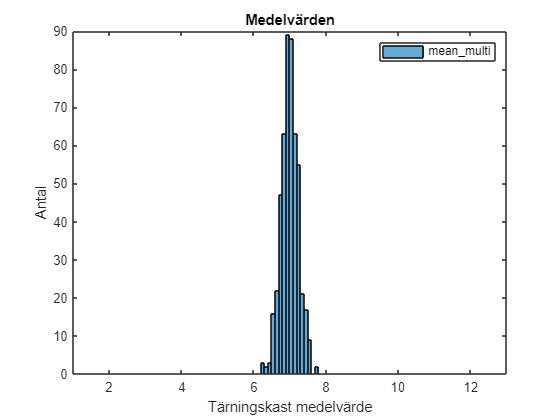


% Så här ser medelvärdena ut från våra 500 experiment
histogram(mean_multi)
title("Medelvärden")
xlabel("Tärningskast medelvärde")
ylabel("Antal")
xlim([1, 13])
legend("mean\_multi")

Från figuren ser vi att medelvärdena skiljer sig lite mellan experimenten eftersom det i slutändan är slumpen som avgör vilket medelvärde vi får.

Vi vill nu visa att spridningen hos medelvärdet då man upprepar experimentet många gånger kan **uppskattas** med hjälp av *standardosäkerheten hos medelvärdet* applicerad på fallet när vi endast utförde experimentet en gång.

% Spridningen i medelvärdet för våra 500 experiment beräknas med
% standardavvikelsen
std_multi = std(mean_multi)

% Uppskattningen av den förväntade spridningen i medelvärdet då vi endast
% utfört ett experiment beräknas med hjälp av formeln för 
% standardosäkerheten hos medelvärdet
uncertainty_single = std(sum_single) / sqrt(length(sum_single))

Jämför de numeriska värdena för *std_multi *och *uncertainty_single*, de bör vara nära varandra (inom ~15 %).

**Slutsats: **Istället för att genomföra experimentet 500 gånger (motsvarande 500 * 100 = 50000 tärningskast) och beräkna *medelvärdet* för varje experiment och se hur det varierar från experiment till experiment (med hjälp av *standardavvikelsen*) så kan vi alltså göra experimentet endast **en** gång och **uppskatta** spridningen med hjälp av *standardosäkerheten hos medelvärdet. *

# Slut på tutorial

## Funktioner

function weighted_dice()
    hold off
    % Kasta två tärningar som är viktade att ge 3 och 4 oftare, 1000 kast.
    weighted_dice_1 = randsample([1, 2, 3, 4, 5, 6], 1000, true, [0.05, 0.1, 0.35, 0.35, 0.1, 0.05]);
    weighted_dice_2 = randsample([1, 2, 3, 4, 5, 6], 1000, true, [0.05, 0.1, 0.35, 0.35, 0.1, 0.05]);
    
    % Summera ögonen på tärningen
    sum_wd = weighted_dice_1 + weighted_dice_2;
    
    % Rita i histogram
    histogram(sum_wd)
    xlabel("Tärningsutslag")
    ylabel("Antal")
    
    % Hitta medelvärde och standardavvikelse
    mean_wd = mean(sum_wd);
    std_wd = std(sum_wd);
    
    % Skriv ut resultat i figuren
    txt_wd = "Viktade tärningar, \mu = " + num2str(mean_wd) + ", \sigma = " + num2str(std_wd);
    title(txt_wd);
    
    % Rita linjer
    xline(mean_wd, "Color", "red", "LineStyle", "--", "LineWidth", 2);
    xline(mean_wd + std_wd, "Color", "green", "LineStyle", "--", "LineWidth", 2);
    xline(mean_wd - std_wd, "Color", "green", "LineStyle", "--", "LineWidth", 2);
end

**Facit - Standardavvikelse**

%{
% Facit:
% Vi beräknar standardavvikelsen med std() funktionen
dice_std = std(dice_sum);

% Vi ritar två gröna streckade linjer i figuren som motsvarar standardavvikelsen
% En till höger om medelvärdet (dice_mean + standardavvikelsen) 
% En till vänster om medelvärdet (dice_mean - standardavvikelsen).
xline(dice_mean + dice_std, "Color", "green", "LineStyle", "--", "LineWidth", 2);
xline(dice_mean - dice_std, "Color", "green", "LineStyle", "--", "LineWidth", 2);

% och skriver ut resultatet i figuren
txt_std = "\sigma = " + num2str(dice_std);
title(txt_mean + " " + txt_std);
%}